clearvars;
load Hmatrix3.mat
c = size(H,2)

c = 12

r = size(H,1)

r = 9

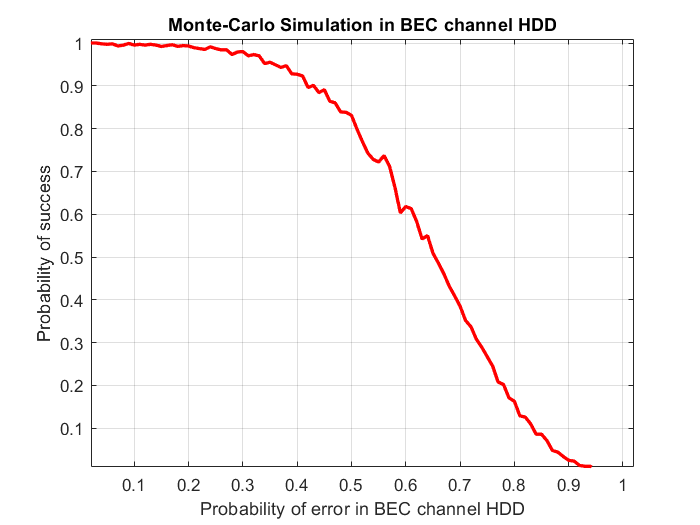

p = 0:0.01:1;
Msg_generated =zeros(1,c);
prob_s = zeros(1,length(p));
kk = 1;
Nsim = 1000;
for d = p
    Sum_s = 0;
    for b = 1:Nsim
        transmitted = zeros(1,c);
        noise = rand(1,c)>1-d;
        for w = 1:c
            if noise(w) == 1
                Msg_generated(w) = -1;
            else
                Msg_generated(w) = xor(noise(w),transmitted(w));
            end
        end
        e_count = 0;
        Msg_generated;
        for z = 1:length(Msg_generated)
            if Msg_generated(z) ~= 0 && Msg_generated(z) ~= 1
                e_count = e_count + 1;
            end
        end
        succ = 1; % Success Counter
        e_count; 
        temp_cnt = 0; %Temporary Counter for storing error count of previous iteration
        itcheck=1; %Number of Iteration
        while e_count > 0 && itcheck<=50
                if temp_cnt == e_count 
                    %disp("This code cant be resolved as it is having errors which cannot be corrected");
                    succ = 0;
                    break;
                end
                temp_cnt = e_count;
                   
            for i = 1 : r
                no1 = 0; %Sum
                nerr = 0; % Number of Erasures
                index = 0;
                for j = 1 : c
                    if H(i,j) == 1
                        if Msg_generated(j) == 1
                            no1 = no1 + 1;
                        elseif Msg_generated(j) == 0
                            no1 = no1 + 0;
                        else
                            nerr = nerr + 1;
                            index = j;
                        end      
                    end
                end
                if nerr == 1
                    Msg_generated(index) = mod(no1,2);
                    e_count = e_count - 1;
                end
                if e_count == 0
                    succ = 1;
                    break;
                end
            end
            itcheck=itcheck+1;
        end
        if succ == 1
            Sum_s = Sum_s + 1;
        end
    end
        prob_s(kk) = Sum_s/Nsim;
        kk = kk + 1;
   
end

plot(p,prob_s,"LineWidth",2,"Color","r");
title("Monte-Carlo Simulation in BEC channel HDD");
xlabel("Probability of error in BEC channel HDD");ylabel("Probability of success"); grid on;
%stem(p,prob_s,"filled","LineWidth",2,"Color","g");
title("Monte-Carlo Simulation in BEC channel HDD");
xlabel("Probability of error in BEC channel HDD");ylabel("Probability of success"); grid on;